# Defining paths

add brainstorm to path addpath(genpath('E:\MATLAB\brainstorm3'));

## setting paths

ft_defaults
bml_defaults
format long

SUBJECT='sub-DM1029';
SESSION='intraop'; 
PATH_DATA='Y:/DBS';
PATH_CORTEX = [PATH_DATA '/derivatives/' SUBJECT '/freesurfer/freesurfer'];
PATH_LOC = [PATH_DATA '/derivatives/' SUBJECT '/freesurfer/freesurfer/Electrode_Locations'];
PATH_PREPROC = [PATH_DATA '/derivatives/' SUBJECT '/preproc'];
PATH_FREESURFER = [PATH_DATA '/derivatives/' SUBJECT '/freesurfer/freesurfer'];
PATH_MNI_BRAIN = "C:\Program Files\LeadDBS_Classic\leaddbs\templates\space\MNI_ICBM_2009b_NLIN_ASYM\cortex\CortexHiRes.mat";
cd(PATH_PREPROC)


Set your leaddbs path according to the subject's derivatives folder in the following priority order: 'Herrington_leaddbs_refined', 'Herrington_leaddbs', or 'leaddbs', 

PATH_LEADDBS = [PATH_DATA '/derivatives/' SUBJECT '/Herrington_leaddbs_refined'];

## B06a: verify ECoG electrode numbering 

LOC_FILE = [PATH_LOC '/CortElecLocL_eq.mat'];

% loading electrode locations on Left side
load(LOC_FILE)
elec = reshape(cell2mat(CortElecLoc),3,length(CortElecLoc))';

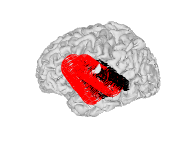

% loading cortex surface
ld = load([PATH_CORTEX '/cortex_indiv.mat']); 
cortex = ld.cortex; 

figure; 
cfg = []; 
% cfg.electrodes = electrode_plot; 
% cfg.snap_elecs_to_surf = true; 
cfg.title = [SUBJECT ' MNI space']; 
cfg.surface_facealpha = 1; 
hF = bml_plot3d_surface(cfg, cortex.vert, cortex.tri); 

% plot electrodes on cortical surface
hold on
plot3(elec(:,1), elec(:,2), elec(:,3), 'o', 'color', 'r', 'MarkerSize', 15)
text(elec(:,1), elec(:,2), elec(:,3), num2str((1:size(elec,1))')); 

After manually navigating and zooming in on the figure, save it for documentation 

exportgraphics(gcf,['figures/ecog_localization/sub-' SUBJECT '_ses-introap_plot-01-native-cortex-ecog-strips.png'],'Resolution',600);

%If Electrodes locations are in incorrect, reorder %defining electrode geometry Nrow=3; NperRow=21; Nstrips = 2; % %choose one of the following reordering schemes, or create a new one 

%(they only work for 1 electrode at a time)
% 
% % % - the following line 'flips' each row in the proximal-distal direction
% % reorder = (ceil((1:(Nrow*NperRow))/NperRow).*NperRow-(1:(Nrow*NperRow))) ...
% %    + 1 + floor((0:(Nrow*NperRow-1))/NperRow).*NperRow;
% 
% % % - the following line 'rotates' the order 180 deg
% %reorder = linspace(Nrow*NperRow, 1, Nrow*NperRow);
% 
% % - the following lines reorder the electrodes if both electrodes are
% % labeled from the left corner instead of the right corner when using
% % surgeon's view.
% reorder = zeros(1,Nrow*NperRow*Nstrips);
% for i = 1:Nstrips
%     for j = 1:Nrow
%         reorder(1,((i-1)*Nrow*NperRow + (j-1)*NperRow + 1):((i-1)*Nrow*NperRow + (j-1)*NperRow + NperRow)) = ((i-1)*Nrow*NperRow + (Nrow - j)*NperRow + 1):((i-1)*Nrow*NperRow + (Nrow - j)*NperRow + NperRow);
%     end
% end
% 
% % - the following lines switch the order of the electrodes themselves
% reorder = zeros(1,Nrow*NperRow*Nstrips);
% for i = 1:Nstrips
%         reorder(1,((i-1)*Nrow*NperRow + 1):(i*Nrow*NperRow)) = ((Nstrips - i)*Nrow*NperRow + 1):((Nstrips - i + 1)*Nrow*NperRow);
% end
% %
% %reordering loaded electrode table
% elec = elec(reorder,:);
% % verify re-ordering by re-plotting
% 
% %Correcting electrode order in CortEleLocL_eq.mat
% %save backup of localization mat files in folder
% %<subject>/Anatomy/FreeSurfer/preop/Electrode_Locations 
% %as CortElecLocL_eq_<date modified>.mat and CortElecLocR_eq_<date modified>.mat
% %if available. Move to archive folder (create if required).
% 
% % %reloading objects
% clear('CortElecLoc','CortElecLoc0')
% load(LOC_FILE)
% 
% %correcting 
% CortElecLoc=CortElecLoc(reorder);
% %CortElecLoc0=CortElecLoc0(reorder);
% 
% %saving
% %save(LOC_FILE,'CortElecLoc','CortElecLoc0')
% save(LOC_FILE,'CortElecLoc')
% %restart script and comment this section out

## Saving electrode coordinates

elec_loc = table((1:size(elec,1))',elec(:,1),elec(:,2),elec(:,3),'VariableNames',{'id','nat_x','nat_y','nat_z'});
writetable(elec_loc,[PATH_LOC '/CortElecLocL_NAT.txt'],'Delimiter','\t')

ans =   11.643505780140856 -15.733380836574156  -1.414146264470673
  12.263847170631156 -14.229627859769439  -0.081328368434061
  11.728693203951796 -14.991419129378025   0.551746898414586
  12.799001137310515 -15.163771448055293   0.248043743943069
  12.884188561121455 -13.291186502262867   1.572305320677811
  12.349034594442095 -14.052977771871454   2.205380587526459
  13.419342527800815 -14.225330090548720   1.901677433054941
  13.535547021136269 -12.871134696179114   3.629436487320536


ans =  -13.163531183940471 -16.156841703167288  -2.170222229141018
 -13.831539391431361 -14.473073786007756  -1.101956983114071
 -14.362128520461166 -15.352495253958526  -0.640878835873598
 -13.300950262401559 -15.117984862677520  -0.346930573414356
 -14.499547598922252 -13.297416717055070   0.371676448559605
 -15.030136727952057 -14.176838185005838   0.832754595800078
 -13.968958469892449 -13.942327793724832   1.126702858259320
 -15.200956216787688 -12.571087642861592   2.324359737463695


## Defining Electrodes table

- Now that we have the coordinates of all the electrodes in the native space, we need to create an electrodes table for easy conversion and documentation in the MNI space. In order to do so, verify that there is already a <subject>_ses-intraop_channels table in derivatives/<subject>/annot.

- Create a copy of the channels table in the same annot folder and rename it **sub-<subject>_electrodes.tsv**. (Or copy an electrodes table from a previous subject)

- Open the fileIn the new file, retain the first 4 columns (onset, duration, name and type) and delete the remaining columns. 

- Delete rows for all non-electrode channels such as blank pins, audio and such.

- For the DBS electrodes, we need to get their native and mni coordinates from the ea_reconstruction.mat file which is an output file of lead DBS (B02). Load the file into MATLAB and open the reco structure. 

ld = load([PATH_LEADDBS filesep 'ea_reconstruction.mat']); 

ans =   11.360300000000001 -14.581500000000000  -9.043010000000001
  11.872800000000000 -13.011699999999999  -7.731000000000000
  11.348699999999999 -13.705900000000000  -7.042220000000000
  12.338500000000000 -13.942299999999999  -7.251920000000000
  12.422499999999999 -11.967499999999999  -6.068980000000000
  11.889300000000000 -12.660399999999999  -5.378660000000000
  12.878100000000000 -12.910500000000001  -5.596300000000000
  13.023000000000000 -11.388100000000000  -3.922220000000000


ld.reco.native.coords_mm{1} % left native
ld.reco.native.coords_mm{2} % right native

ans =  -12.617800000000001 -15.529500000000001  -8.892870000000000
 -13.279600000000000 -13.692299999999999  -7.890690000000000
 -13.720400000000000 -14.571400000000001  -7.264150000000000
 -12.714600000000001 -14.219600000000000  -7.109240000000000
 -13.935800000000000 -12.335900000000001  -6.407770000000000
 -14.358900000000000 -13.222500000000000  -5.787450000000000
 -13.366800000000000 -12.864100000000001  -5.644110000000000
 -14.575300000000000 -11.369899999999999  -4.327350000000000


ld.reco.mni.coords_mm{1}; % left mni

ld.reco.mni.coords_mm{2}

- The data of interest is under native and mni for the two coordinate systems respectively. In each case, the 1st cell contains coordinates for the Right electrode and the 2nd cell has coordinates for the Left electrode. When numbering the electrodes, for directed electrodes, use 1, 2A, 2B, 2C, 3A, 3B, 3C and 4. For undirected electrodes, use 1 through number of electrodes.

- For any electrodes that changed position during the experiment, be sure to duplicate their rows as many times as necessary to capture all changes during recordings.

- Calculate the onset and duration in seconds from midnight on the day of the surgery from the implanted and explanted time on the CRF as shown in the example below and populate the first two columns accordingly.

- If an electrode is not connected during the experiment (as the right DBS electrode below), set onset and duration both to 0.

The following lines transforms native coordinates to mni space using leaddbs. keep a copy of each subjects files with each subject also using as a template for subsequent files.

% loading electrode table
electrode = bml_annot_read_tsv([PATH_DATA '/derivatives/' SUBJECT filesep 'annot' filesep SUBJECT '_electrodes.tsv']);

% recalculating mni_nonlinear coords using lead DBS's 
anchor_modality = [PATH_LEADDBS filesep 'anat_t1.nii'];
assert(isfile(anchor_modality),'file %s does not exist',anchor_modality);
warp_file = [PATH_LEADDBS filesep 'glanatInverseComposite.nii.gz'];
assert(isfile(warp_file),'file %s does not exist',warp_file);

leadDBS_mm = [electrode.native_x, electrode.native_y, electrode.native_z]';
leadDBS_mm = [leadDBS_mm; ones(1,size(leadDBS_mm,2))];
[~, leadDBS_vx] = ea_map_coords(leadDBS_mm, anchor_modality);
mni_nonlinear_mm = ea_map_coords(leadDBS_vx, anchor_modality, warp_file,[], 'ANTS',0)';

isCortElec = ismember(electrode.type,{'ECOG'});
electrode(isCortElec,{'mni_x','mni_y','mni_z'}) = ...
    num2cell(mni_nonlinear_mm(isCortElec,1:3));

type= {'ECOG','DBS','SEEG','MICRO'}';
sigma=[1.5,     1,     1,      0.5]';

electrode(:,startsWith(electrode.Properties.VariableNames,'DISTAL'))=[];
cfg=[];
cfg.atlas = 'DISTAL All (Ewert 2017)';
cfg.label_column_basename = 'DISTAL';
cfg.max_assign = 3;
cfg.sigma = bml_map(electrode.type,type,sigma,nan);
cfg.radius = 3;
anat_labels = bml_anat_coord2label(cfg,electrode(:,{'id','mni_x','mni_y','mni_z'}));
electrode = join(electrode,anat_labels);

electrode(:,startsWith(electrode.Properties.VariableNames,'HCPMMP1'))=[];
cfg=[];
cfg.atlas = 'HCPMMP1 (Glasser 2016)';
cfg.label_column_basename = 'HCPMMP1';
cfg.max_assign = 2;
cfg.sigma = bml_map(electrode.type,type,sigma,nan);
cfg.radius = 5;
anat_labels = bml_anat_coord2label(cfg,electrode(:,{'id','mni_x','mni_y','mni_z'}));
electrode = join(electrode,anat_labels);

bml_annot_write_tsv(electrode, [PATH_DATA '/derivatives/' SUBJECT filesep 'annot' filesep SUBJECT '_electrodes.tsv']);

The following lines transforms electrode coordinates and brain surface coordinates from individual space to MNI space Template script. Keep one for each subject Export brainstorm matlab file to matlab as sMRI before running this script

## Loading required objects

% load standard MNI brain for plotting
load(PATH_MNI_BRAIN, 'Vertices', 'Faces');

% load cortical surface 
load([PATH_FREESURFER filesep 'cortex_indiv.mat'], 'cortex');

% load T1 image, freesurfer function MRIread.m required
f = MRIread([PATH_FREESURFER filesep 'mri\T1.nii']);

% load in sMRI if not already in the workspace
%load([PATH_FREESURFER filesep 'sMRI_' SUBJECT])

% vox2ras transformation matrix
vox2ras = [1,0,0,-128;0,1,0,-128;0,0,1,-128;0,0,0,1];

## debugging non-appearance of hcpmmp1 atlas labels

figure; % MNI electrode plotted with MNI brain
Hp = patch('vertices', Vertices,'faces', Faces,...
    'facecolor',[.50 .50 .50],'edgecolor','none',...
    'facelighting', 'gouraud', 'specularstrength', .50);
camlight('headlight','infinite');
axis off; axis equal
alpha 0.5
hold on; plot3(mni_nonlinear_mm(1:126,1), mni_nonlinear_mm(1:126,2), mni_nonlinear_mm(1:126,3), 'b.', 'MarkerSize', 15)



cfg = []; 
% cfg.electrodes = electrode_plot; 
% cfg.snap_elecs_to_surf = true; 
cfg.title = [SUBJECT ' MNI space']; 
cfg.surface_facealpha = 1; 
hF = bml_plot3d_surface(cfg, Vertices, Faces); 